clc, clear all

## Data of IM

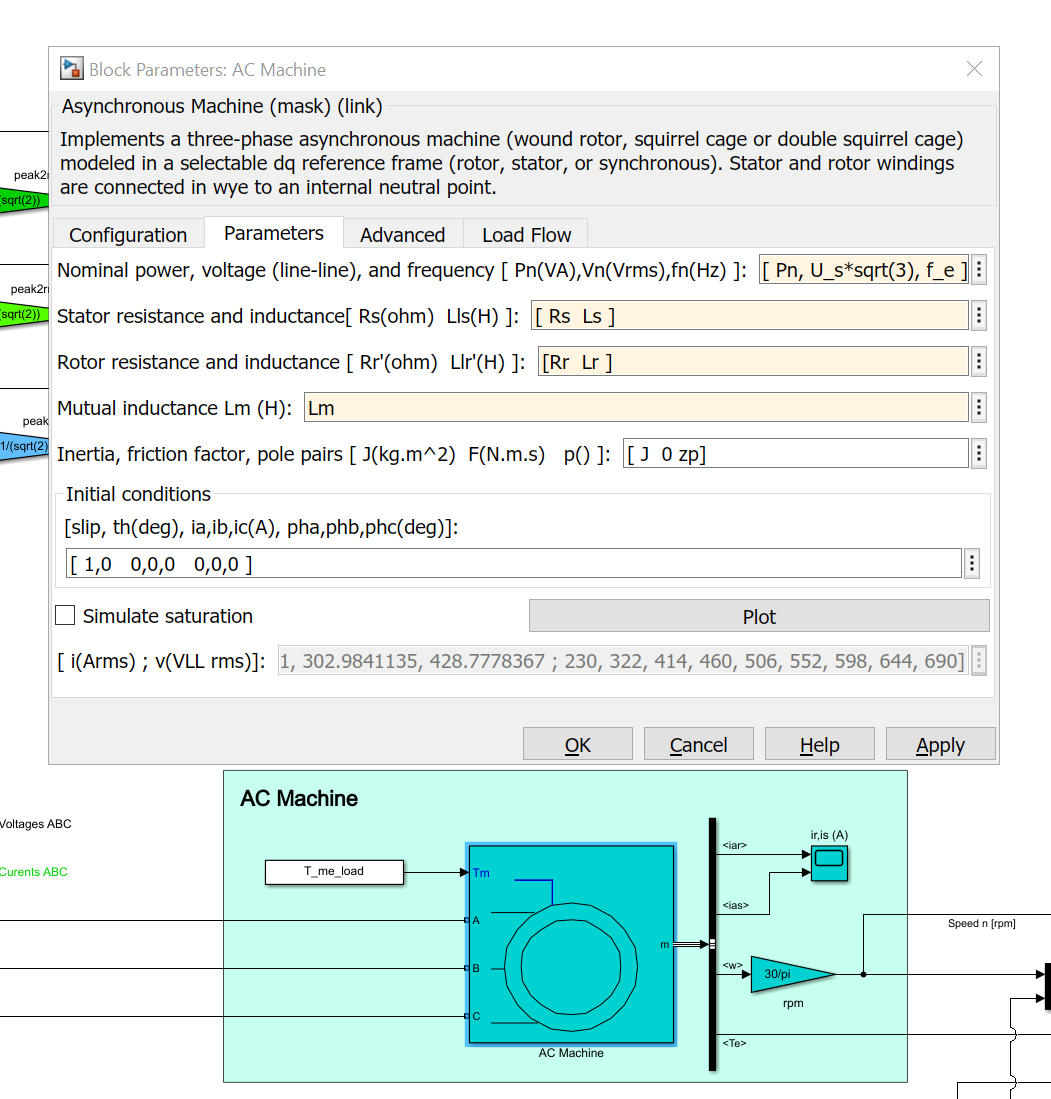x

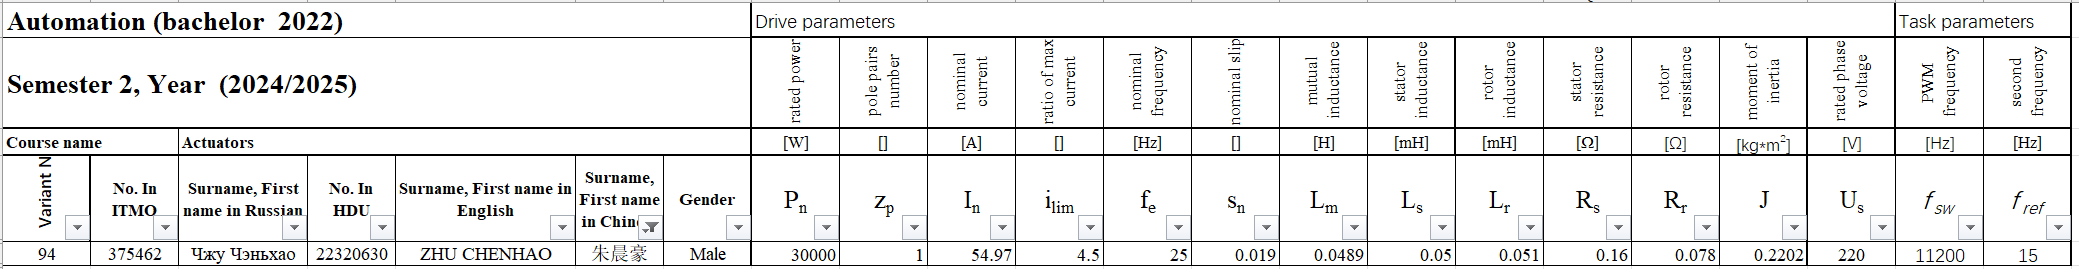

Pn          =       30000                   % - rated power, [W]

Pn = 30000

zp          =       1                      % - pairs of poles

zp = 1

f_e         =       25;                    % - nominal (rated) frequency, [Hz]
s_n         =       0.019                  % - nominal slip

s_n = 0.0190

I_n         =       54.97;                  % - nominal (rated)current, [А]
i_lim       =       4.5;                   % - ratio of max current
Lm          =       0.0489                % - mutual inductance, [H]

Lm = 0.0489

Ls          =       0.05e-3                 % - stator inductance, [H]

Ls = 5.0000e-05

Lr          =       0.051e-3                % - rotor inductance, [H]

Lr = 5.1000e-05

Rs          =       0.16                % - stator resistance,  [Оhm]

Rs = 0.1600

Rr          =       0.078               % - rotor resistance,  [Оhm]

Rr = 0.0780

J           =       0.2202                 % - moment of inertia , [kg*m2]

J = 0.2202

km          =       i_lim

km = 4.5000

$T_{e_{\textrm{rated}} } =\frac{P_n *z_p }{2*\pi *f_e *\left(1-s_n \right)}*60$ [N*m]

T_e_rated  =      Pn*zp/((1-s_n)*2*pi*f_e) % - nominal (rated) torque, [N*m]

T_e_rated = 194.6849

$\omega_{\mathrm{rated}} =2*\pi *f_e *\frac{\left(1-s_n \right)}{z_p }$ [rad/s]w_rated     =       2*pi*f_e*(1-s_n)/zp   % - rated speed [rad/s]

w_rated  =        2*pi*f_e*((1-s_n)/zp)

w_rated = 154.0951

$\omega_{\textrm{idle}} =\frac{2*\pi *f_e }{z_p }$ [rad/s]

w_idle      =       2*pi*f_e/zp;            % - idle speed [rad/s]    

## PWM simulation parameters

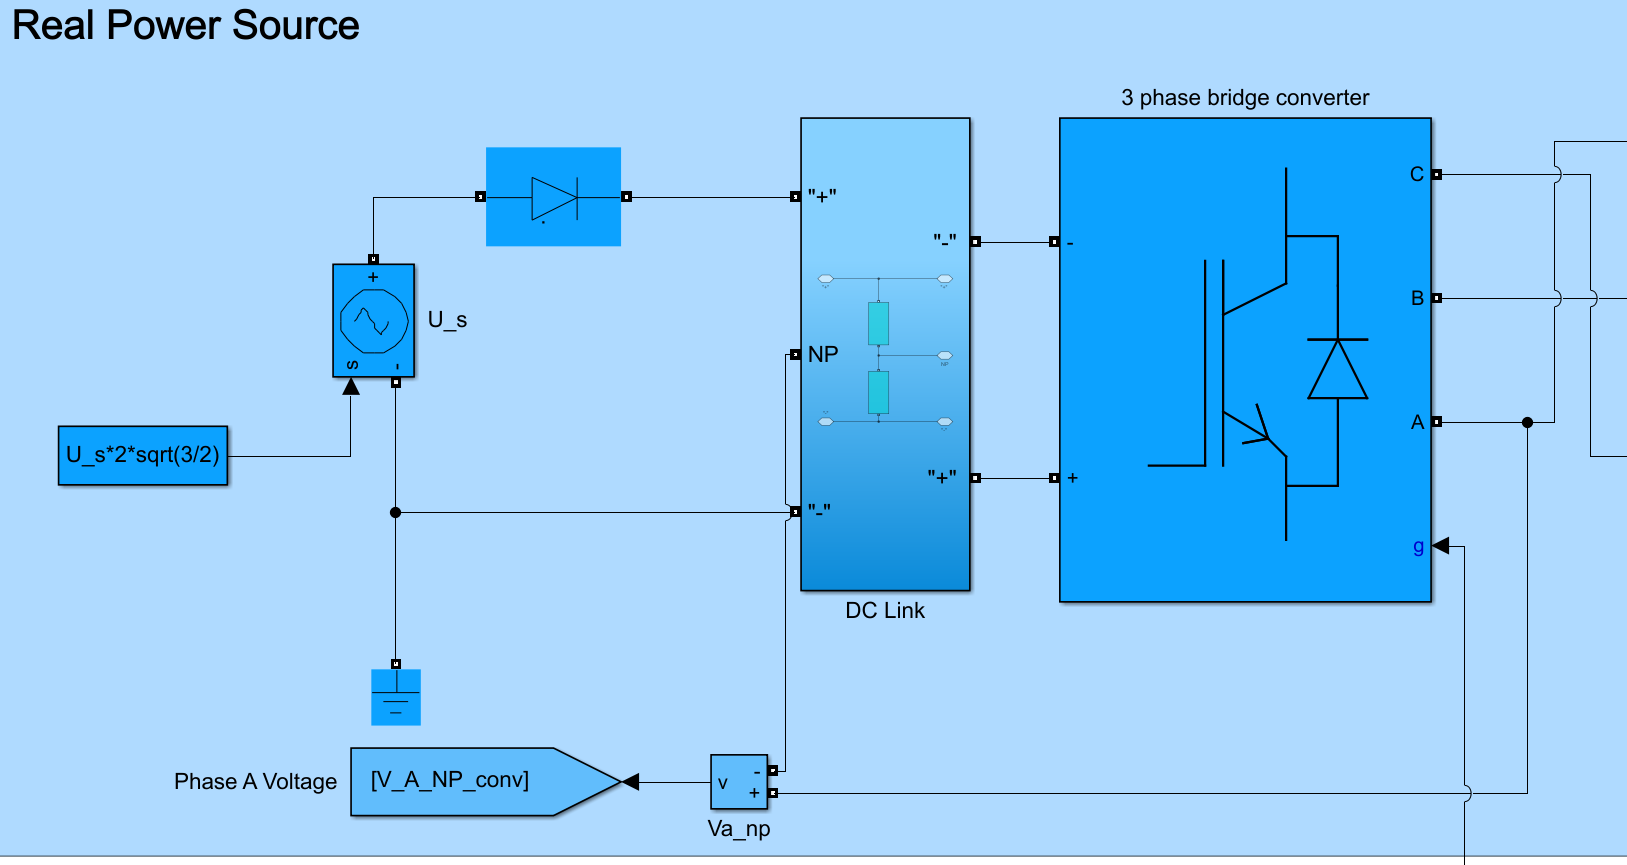

$n_{\mathrm{rated}} =\frac{\omega_{\mathrm{rated}} }{2*\pi }*60$ [rpm]

n_rated    =        w_rated/2/pi*60        % - rated speed [rpm]

n_rated = 1.4715e+03

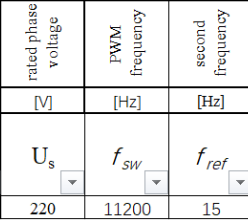

U_s         =      220;                     % - phase (rated) voltage, V 
f_sw        =      11200;                   % - PWM frequency, Hz   
f_ref       =      15              % - second required speed stator current frequency , [Hz]

f_ref = 15

$n_{\textrm{ref}} =60*f_{\textrm{ref}} *\frac{\left(1-s_n \right)}{z_p }$ [rpm]

n_ref       =      f_ref/zp*60*(1-s_n)        % - second required speed stator current frequency , [Hz]

n_ref = 882.9000

### Frequency modulation index


$$m_f =\frac{f_{\textrm{sw}} }{f_e }$$


m_f         =       f_sw/f_e                 % - Frequency modulation index at rated speed

m_f = 448

### Switching frequency

f_sw        =       f_e*m_f

f_sw = 11200

w_ref       =       1                        % - speed reference (p.u.)

w_ref = 1

## Uncomment lines 26-28 to simulate second required speed

### Speed reference

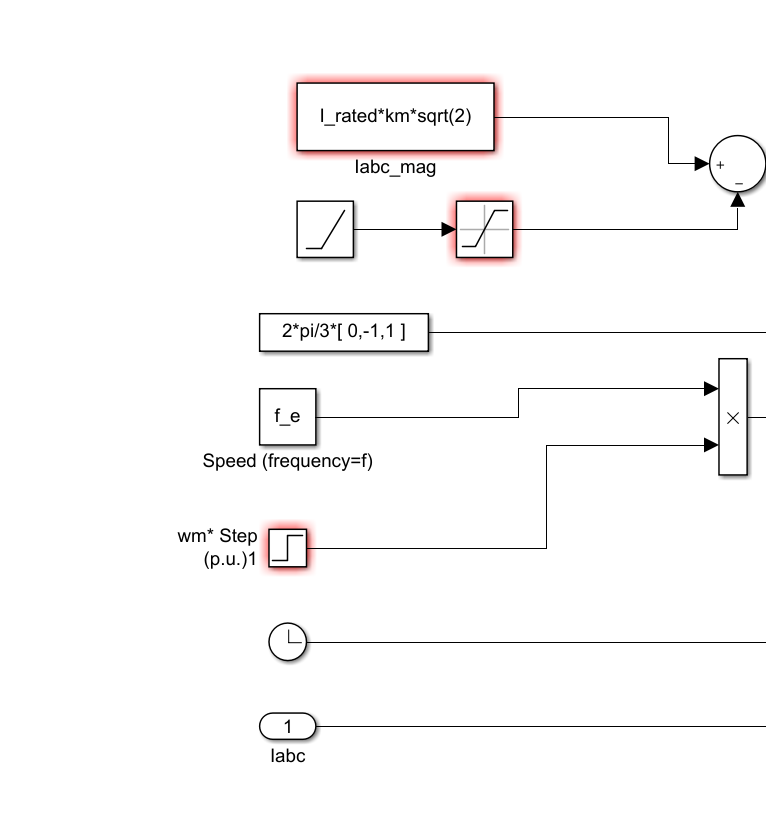    

% m_f         =       f_sw/f_ref               % - Frequency modulation index at second required speed
% f_e         =       f_ref
% w_ref       =       n_ref/n_rated            % - voltage reference (p.u.) - this setting automatically do Us/f_e=const

### Load torque

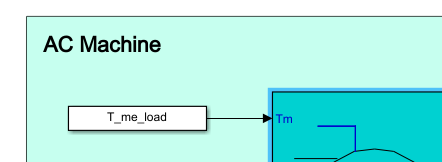

T_me_load   =       1.0*T_e_rated            % - Load torque, [N*m]

T_me_load = 194.6849